**Part 1:**

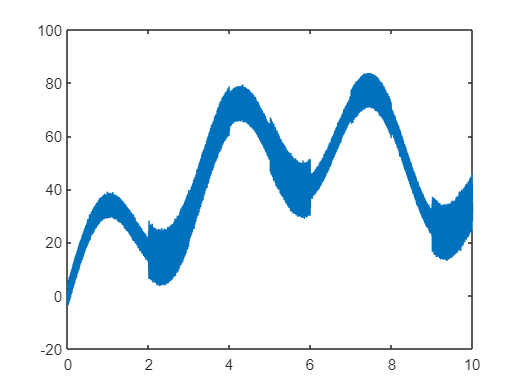

Y = HW2_sig(810199570);
t = 0:0.00001:10;
plot(t, Y)

**Part 2:**

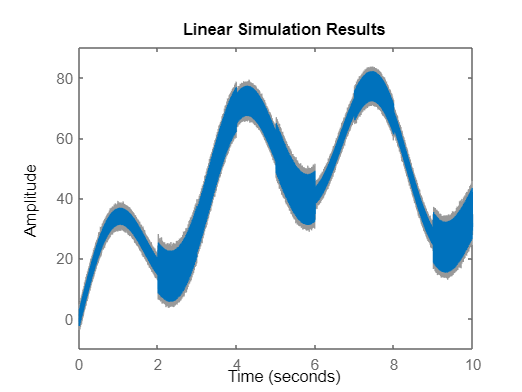

s = tf('s');
f = 500;
RC = 1/(2*pi*f);
G = 1/(RC*s+1);
lsim(G,Y,t)

**Part 3:**

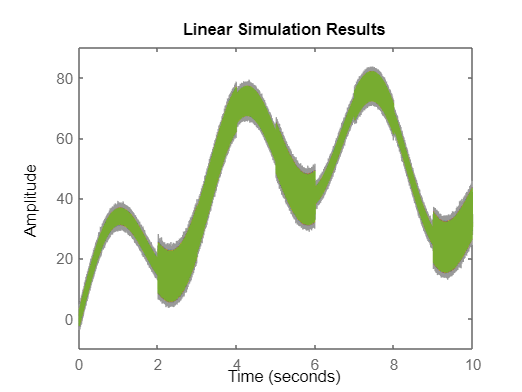

f_m = [0 0 0 0 0];
RC_m = [0 0 0 0 0];
for i=1:5
    f_m(i) = 475+25*i;
    RC_m(i) = 1/(2*pi*f_m(i));
end
G1 = 1/(RC_m(1)*s+1);
G2 = 1/(RC_m(2)*s+1);
G3 = 1/(RC_m(3)*s+1);
G4 = 1/(RC_m(4)*s+1);
G5 = 1/(RC_m(5)*s+1);
lsim(G5, G4, G3, G2, G1,Y,t)

**Part 4:**

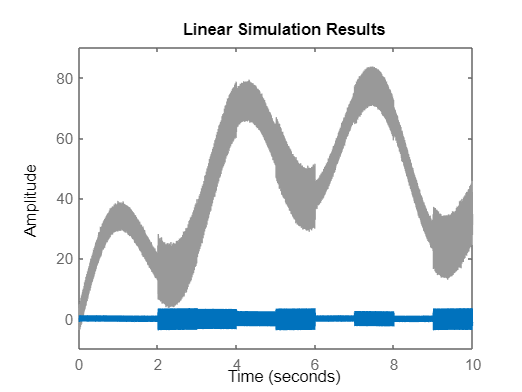

fH = 101;
fL = 99;
RCH = 1/(2*pi*fH);
RCL = 1/(2*pi*fL);
G = RCH*s/((RCH*s+1)*(RCL*s+1));
lsim(G, Y, t);

**Part 5:**

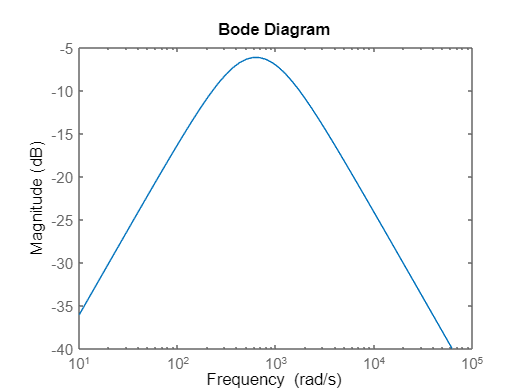

bodemag(G);

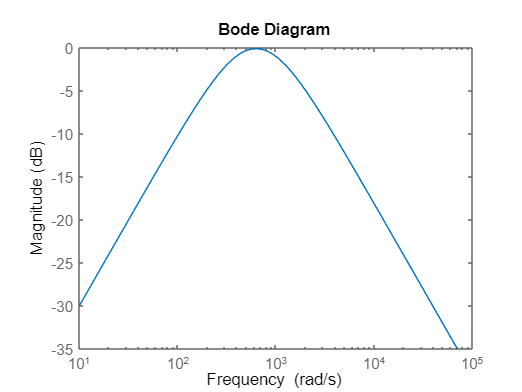

k = 2;
kG = k*G;
bodemag(kG);

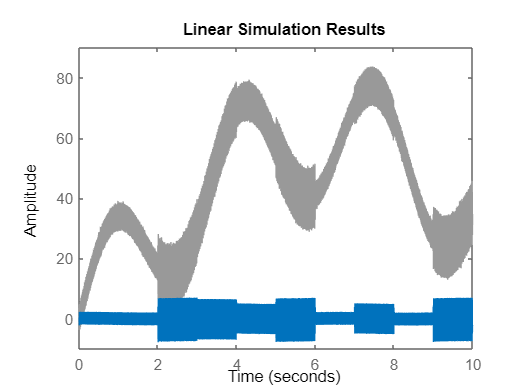

lsim(kG, Y, t);

**Part 6:**

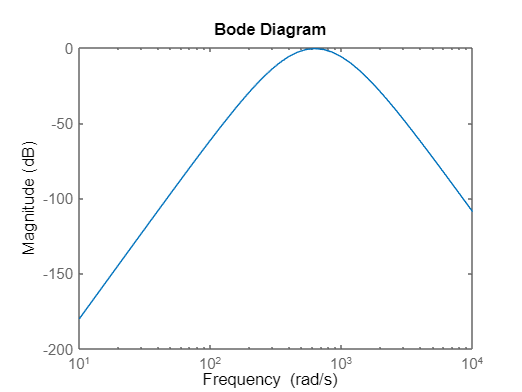

n = 6;
F = (kG)^n;
bodemag(F);

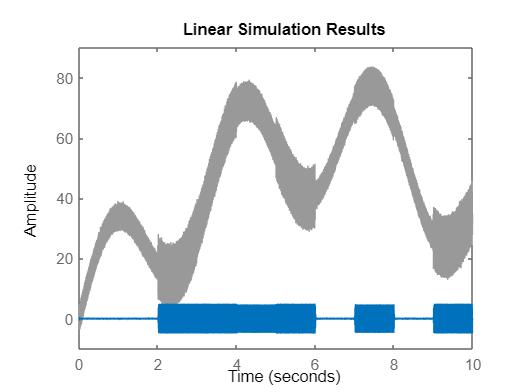

lsim(F, Y, t)

**Part 7: (for 3v & 250Hz)**

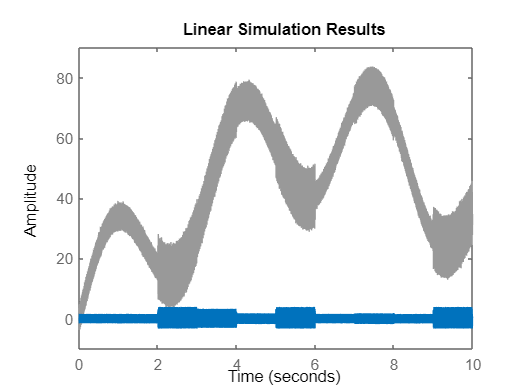

fH = 251;
fL = 249;
RCH = 1/(2*pi*fH);
RCL = 1/(2*pi*fL);
G = RCH*s/((RCH*s+1)*(RCL*s+1));
lsim(G, Y, t);

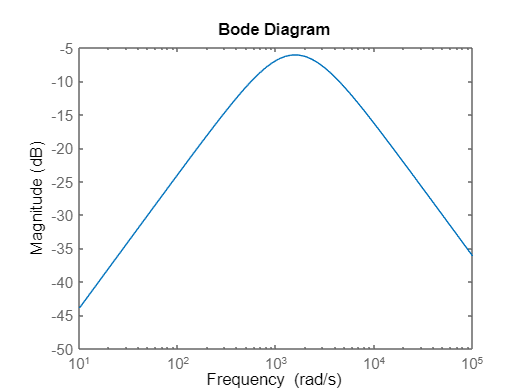

bodemag(G);

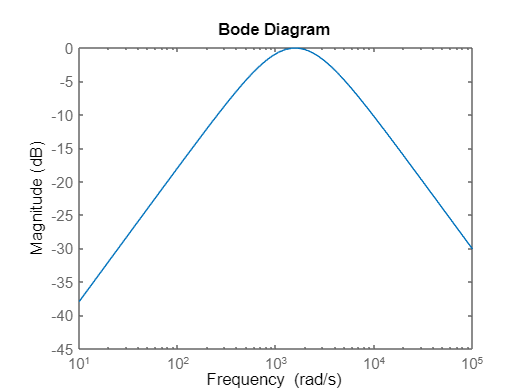

k = 2;
kG = k*G;
bodemag(kG);

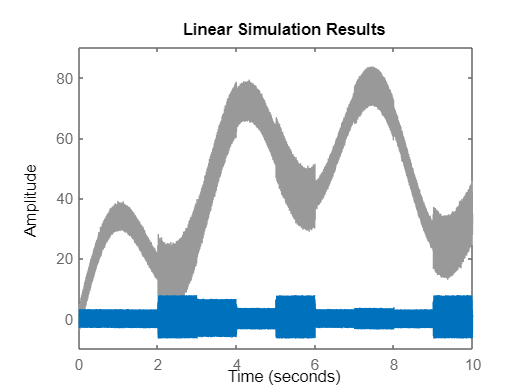

lsim(kG, Y, t);

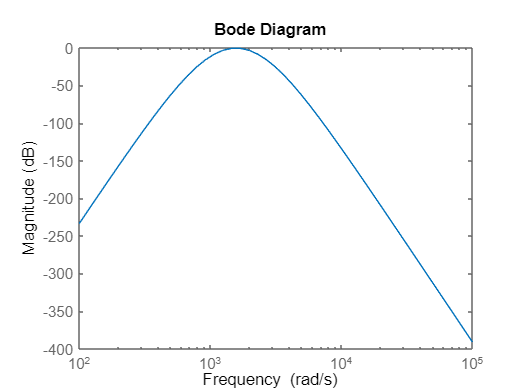

n = 13;
F = (kG)^n;
bodemag(F);

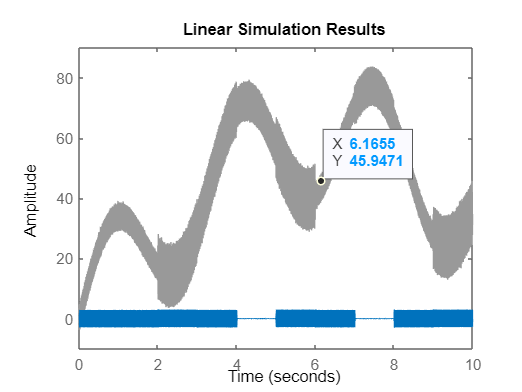

lsim(F, Y, t)

**Part 7: (for 4v & 500Hz)**

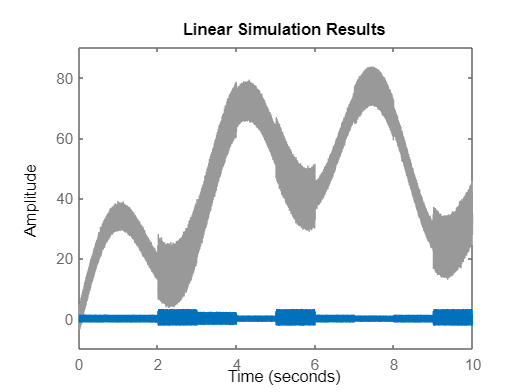

fH = 501;
fL = 499;
RCH = 1/(2*pi*fH);
RCL = 1/(2*pi*fL);
G = RCH*s/((RCH*s+1)*(RCL*s+1));
lsim(G, Y, t);

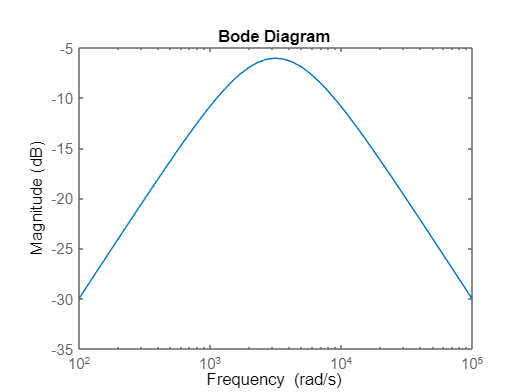

bodemag(G);

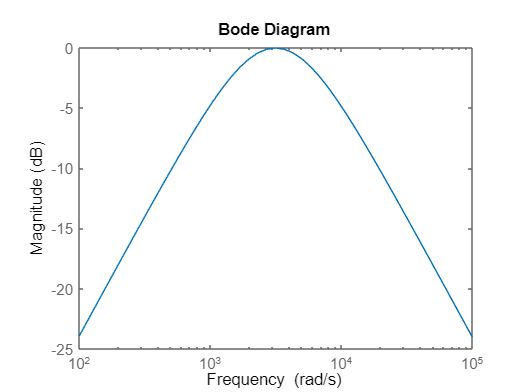

k = 2;
kG = k*G;
bodemag(kG);

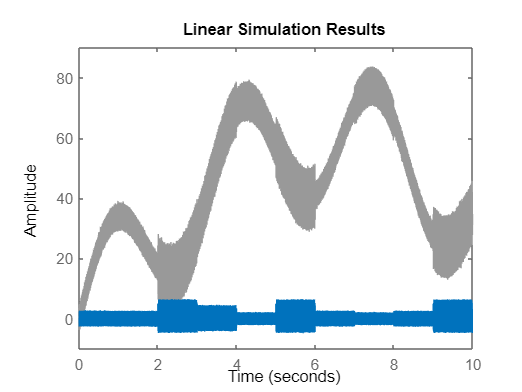

lsim(kG, Y, t);

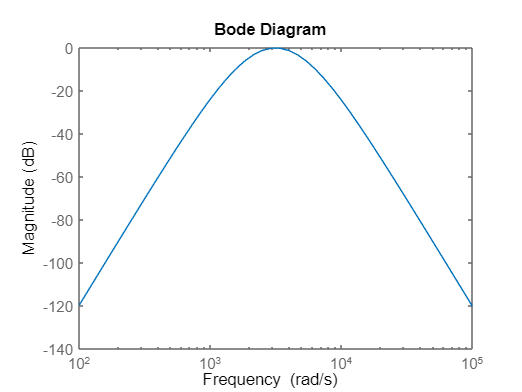

n = 5;
F = (kG)^n;
bodemag(F);

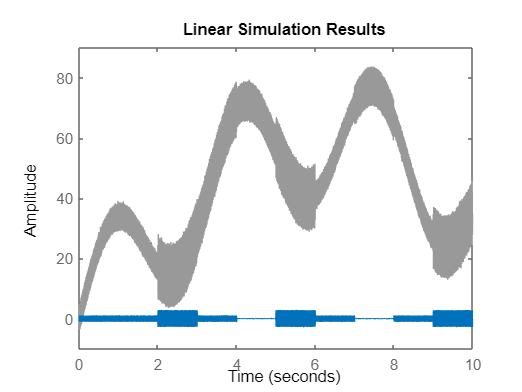

lsim(F, Y, t)

**Part 9:**

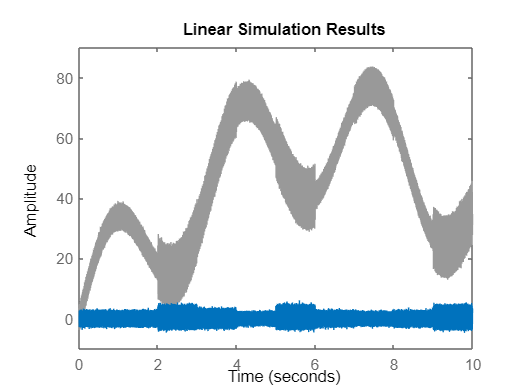

f = 500;
RC = 1/(2*pi*f);
G = RC*s/(RC*s+1);
lsim(G, Y, t);

**Part 10:**

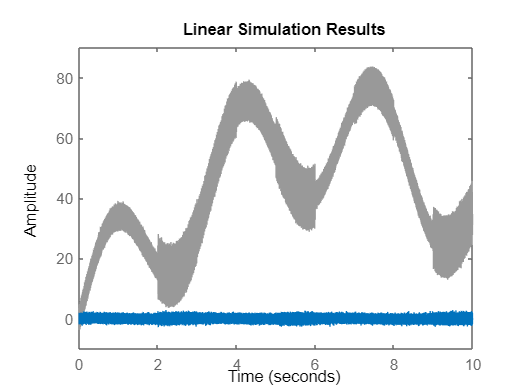

f1 = 100;
RC1 = 1/(2*pi*f1);
f2 = 250;
RC2 = 1/(2*pi*f2);
f3 = 50;
RC3 = 1/(2*pi*f3);
G1 = (((RC1*s)^2)+1)/(((RC1*s)^2)+4*RC1*s+1);
G2 = (((RC2*s)^2)+1)/(((RC2*s)^2)+4*RC2*s+1);
G3 = RC3*s/(RC3*s+1);
G = G1*G2*G3;
lsim(G, Y, t);